% load exp1.mat
% load exp2.mat
% load exp3.mat
% load best_policies_stats.mat
% %load agents.mat
% 
% PS = PLOT_STANDARDS();
% 
% ep_timeline = exp1.ep_timeline;
% RFs_return = exp1.RFs_return;
% shorter_ep_timeline = exp1.shorter_ep_timeline;
% mean_RFs_norm = exp1.mean_RFs_norm;
% idx = exp1.best_idx;

%SAC_agent = SAC_agents{3};
datalogger = SAC_agent.datalogger;
    

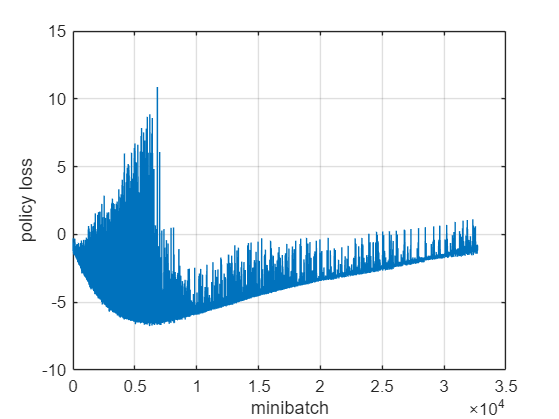

% best_RF2_idx = stats.best_policy_idx(idx(2),2);
% datalogger = agents(idx(2),2).datalogger;
figure
plot(datalogger.policy_loss(datalogger.policy_loss~=0))
xlabel('minibatch')
ylabel('policy loss')
grid on

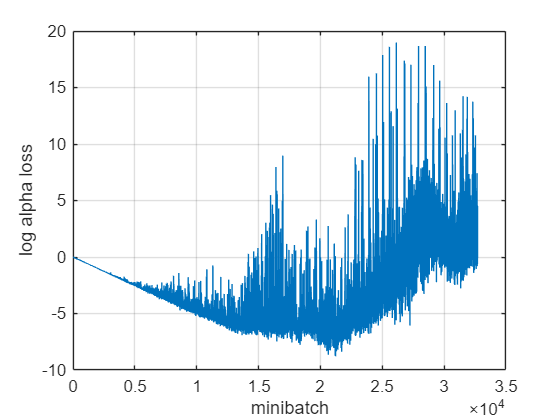

figure
plot(datalogger.log_alpha_loss(datalogger.log_alpha_loss~=0))
xlabel('minibatch')
ylabel('log alpha loss')
grid on

% figure
% plot(datalogger.log_alpha_grad)
% xlabel('time steps')
% ylabel('log alpha grad')
% grid on

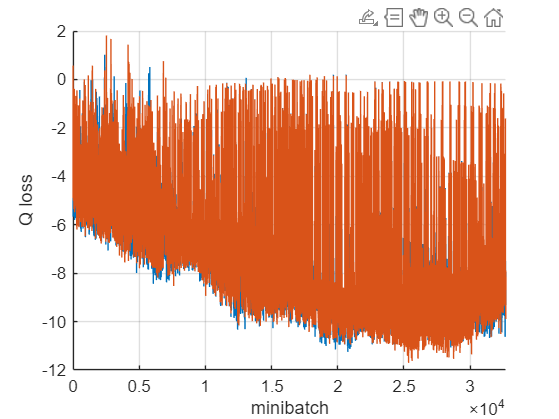

figure
hold on
%plot((datalogger.Q1_loss(datalogger.Q1_loss~=0)))
%plot((datalogger.Q2_loss(datalogger.Q2_loss~=0)))
plot((log(datalogger.Q1_loss(datalogger.Q1_loss~=0))))
plot(log((datalogger.Q2_loss(datalogger.Q2_loss~=0))))
%ylim([0 50])
xlim([0 length(datalogger.Q1_loss(datalogger.Q1_loss~=0))])
xlabel('minibatch')
ylabel('Q loss')
grid on
hold off

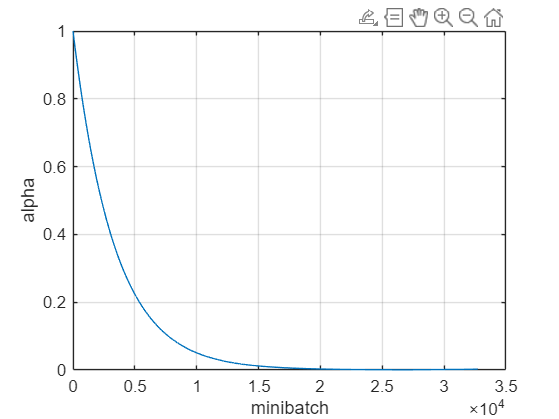

figure
plot(datalogger.alpha(datalogger.alpha~=0))
xlabel('minibatch')
ylabel('alpha')
grid on

% figure
% plot(log(datalogger.alpha(datalogger.alpha~=0)))
% xlabel('minibatch')
% ylabel('log alpha')
% grid on

% step_clock =  datalogger.step_clock(datalogger.step_clock < 1);
% figure()
% plot(step_clock)
% xlabel('time steps')
% ylabel('real time step duration')
% grid on

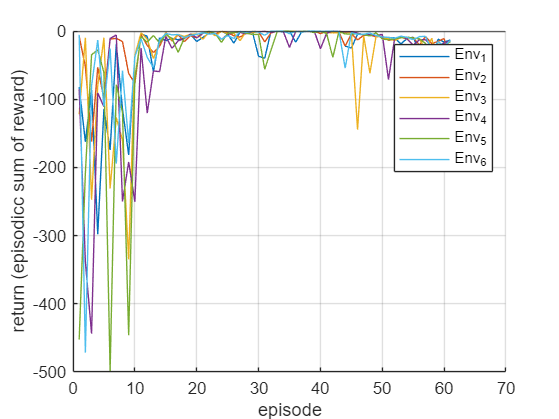

mean_return = movmean(datalogger.ep_return, 50);
figure
hold on
%plot(datalogger.ep_return)
plot((datalogger.ep_return./datalogger.ep_length)*1000)
%plot(mean_return, LineWidth=2)
yline(0)
legend('return', 'movmean,win=50')
xlabel('episode')
ylabel('return (episodicc sum of reward)')
%legend(["return", "movmean,win=50"], "Position", [0.6417 0.6820 0.2607, 0.0774])
legend('Env_1', 'Env_2', 'Env_3', 'Env_4', 'Env_5', 'Env_6')
hold off
grid on

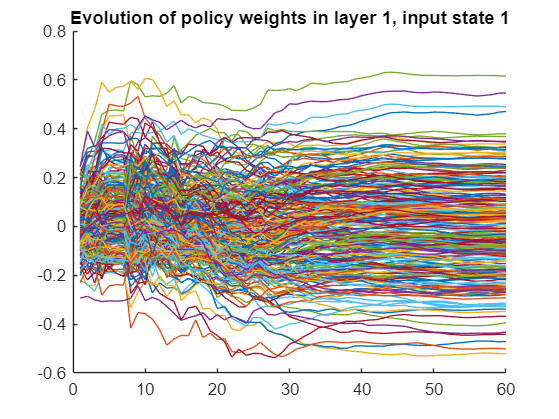

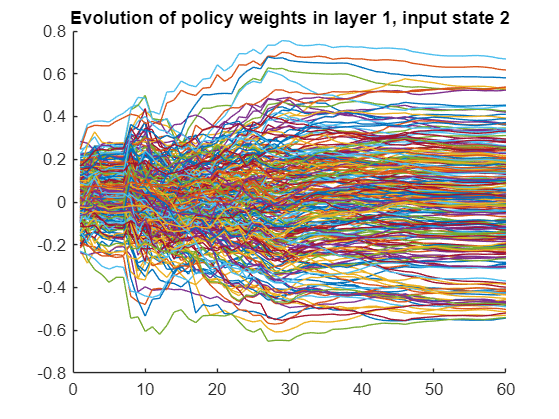

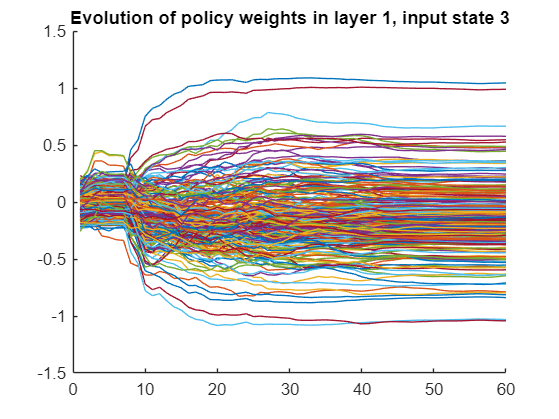

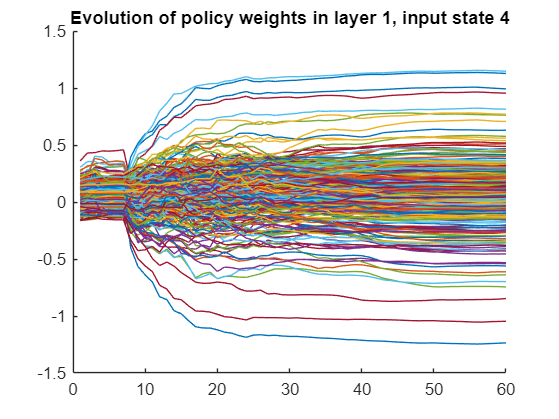

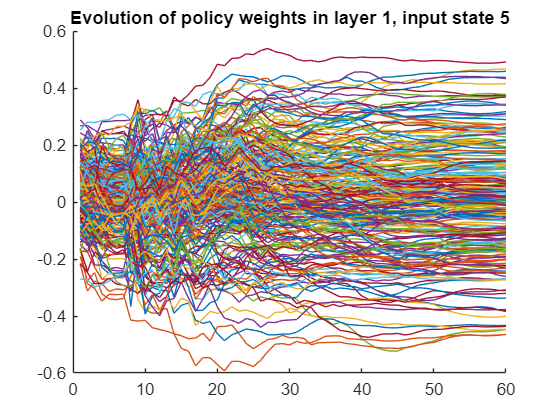

for i = 1:SAC_agent.epoch_count-1
    actor_net_weights{i} = datalogger.actor.policy.net(i).Learnables.Value;
    Q1_net_weights{i} = datalogger.critic(i).Q1.net.Learnables.Value;

    policy_fc1{i} = actor_net_weights{i}{1,1};
    for s = 1:datalogger.bounds.state_space_size
        policy_weights_fc1{s}(:,i) = policy_fc1{i}(:,s); % rows are weights (32), columns are episodes
    end

    Q1_fc_1{i} = Q1_net_weights{i}{1,1};
    Q1_fc_2{i} = Q1_net_weights{i}{3,1};

    for s = 1:datalogger.bounds.state_space_size
        Q1_weights_fc1{s}(:,i) = Q1_fc_1{i}(:,s); % rows are weights (32), columns are episodes
    end
    for s = 1:datalogger.bounds.action_space_size
        Q1_weights_fc2{s}(:,i) = Q1_fc_2{i}(:,s); % rows are weights (32), columns are episodes
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for s = 1:datalogger.bounds.state_space_size
    figure
    hold on
    for n = 1:size(policy_weights_fc1{s},1)
        plot(policy_weights_fc1{s}(n,:))
    end
    xlim([0, size(policy_weights_fc1{s},2)])
    title("Evolution of policy weights in layer 1, input state " + num2str(s))
end

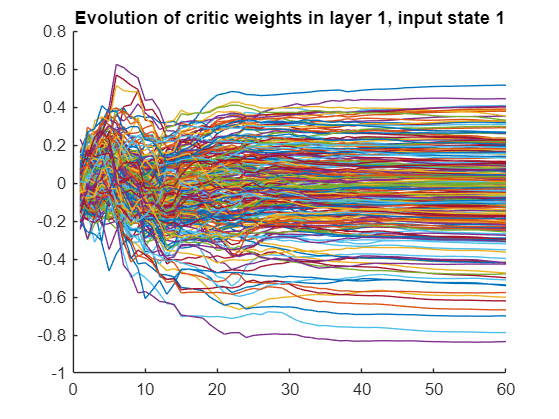

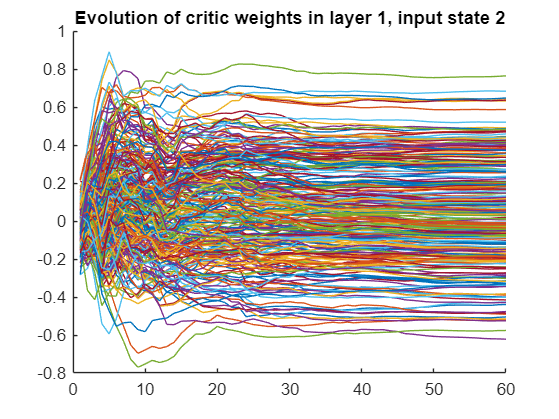

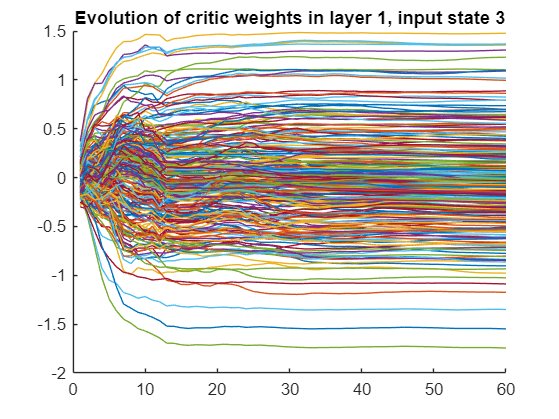

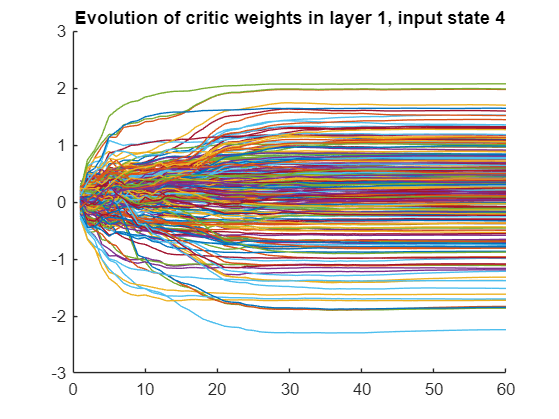

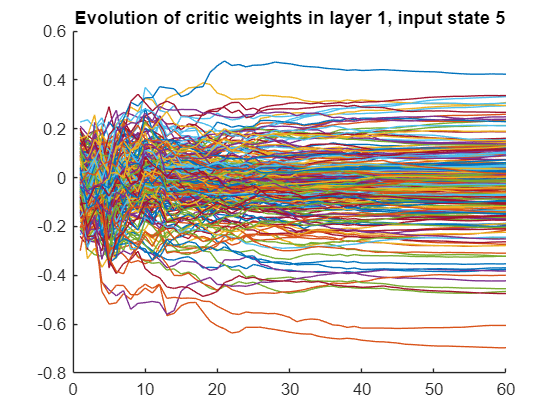

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for s = 1:datalogger.bounds.state_space_size
    figure
    hold on
    for n = 1:size(Q1_weights_fc1{s},1)
        plot(Q1_weights_fc1{s}(n,:))
    end
    xlim([0, size(Q1_weights_fc1{s},2)])
    title("Evolution of critic weights in layer 1, input state " + num2str(s))
end

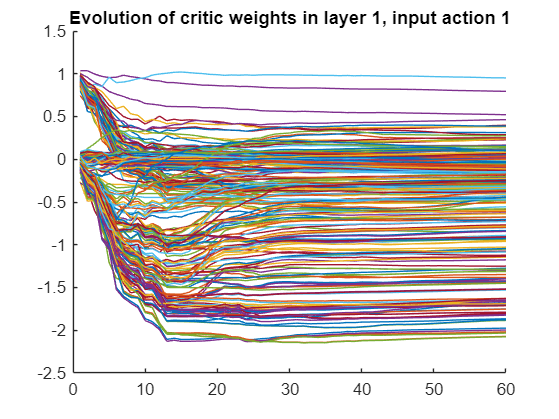


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for s = 1:datalogger.bounds.action_space_size
    figure
    hold on
    for n = 1:size(Q1_weights_fc2{s},1)
        plot(Q1_weights_fc2{s}(n,:))
    end
    xlim([0, size(Q1_weights_fc2{s},2)])
    title("Evolution of critic weights in layer 1, input action " + num2str(s))
end

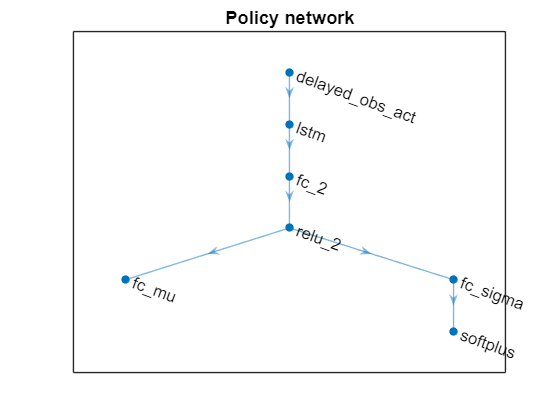

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



figure
plot(datalogger.actor.policy.net(1))
title('Policy network')

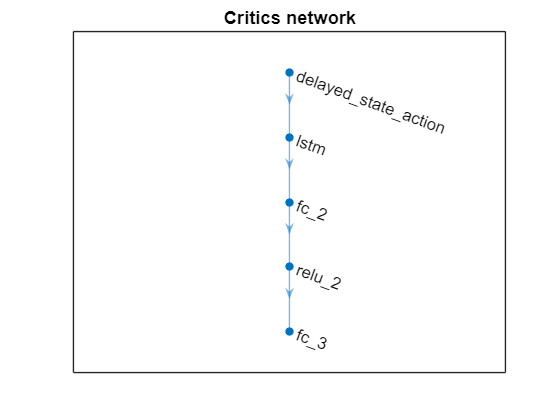


figure
plot(datalogger.critic(1).Q1.net)
title('Critics network')